# Load resources

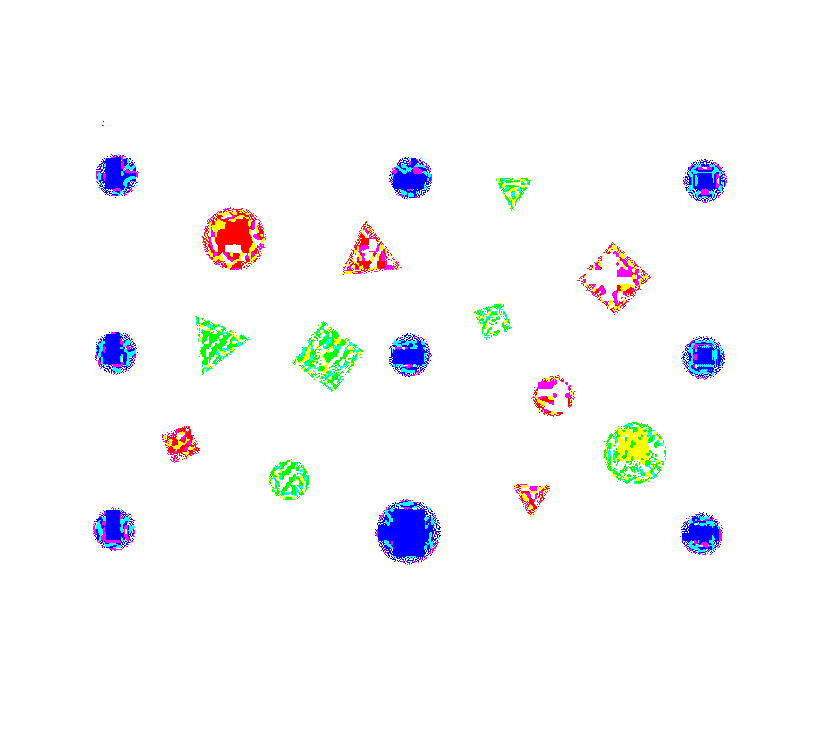

clear All; close all;
capture = double(imread("capture.jpg"));
init_image = double(imread("init_image2.jpg"));
dest_image = double(imread("init_image3.jpg"));
imshow(capture)

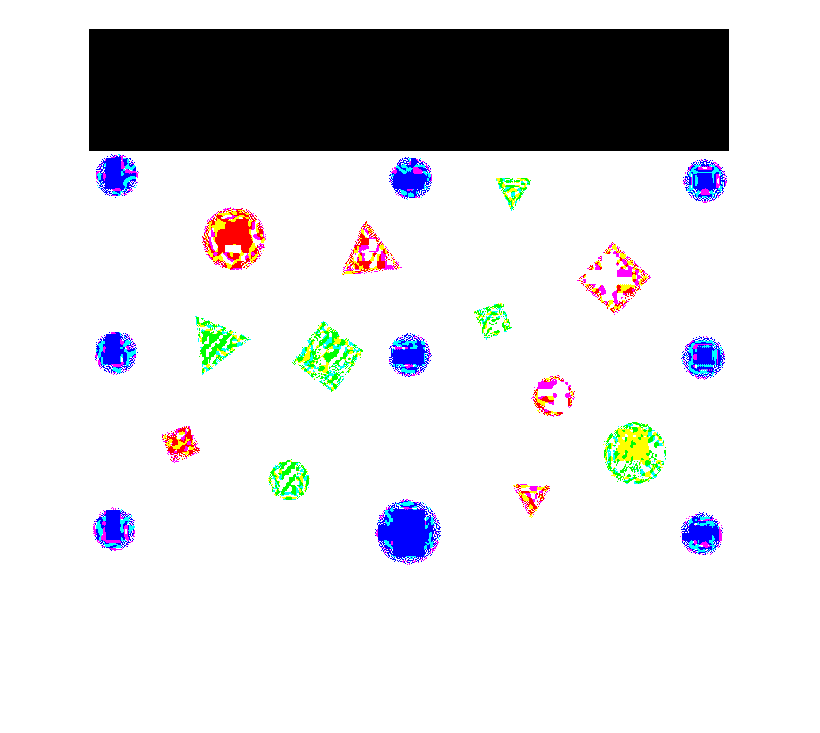


% % Zero the text part
% plainImage = plainSpace;
% plainImage(:,3015:end,:) = 0;
% imshow(plainImage)

% Zero the text part
plainImage = capture;
plainImage(1:122,:,:) = 0;
% plainImage = plainSpace(:,1:3015,:); %double(plainspace(60:4619,129:2995,:));
imshow(plainImage)

## Run

% % Get colour plains
% red = plainImage(:,:,1);
% green = plainImage(:,:,2);
% blue = plainImage(:,:,3);
% imshow(blue)
% 
% % Get blue circles
% blueCircles = imclose(blue./(red+green+blue) > 0.5, ones(4,4));
% figure; imshow(blueCircles); title("blueCircles");
% 
% % get red shapes
% % Old method to filter noise: redBinary = medfilt2(red./(red+green+blue) > 0.45, [3,3]);
% redBinary = imclose(red./(red+green+blue) > 0.5, ones(4,4));
% figure; imshow(redBinary); title("redBinary");
% 
% % Get green shapes
% green = green./(red+green+blue) > 0.5;
% greenBinary = imclose(green, ones(5,5));
% figure; imshow(greenBinary); title("greenBinary"); 

% 
% % Get data from sheet
% % Get blue centroids
% blueStats = regionprops("table",blueCircles,"Centroid","Area","Circularity");
% imshow(blueCircles)
% hold on
% plot(blueStats.Centroid(:,1),blueStats.Centroid(:,2),"b*")
% hold off
% 
% % Get red centroids
% redStats = regionprops("table",redBinary,"Centroid","Area","Circularity");
% imshow(redBinary)
% hold on
% plot(redStats.Centroid(:,1),redStats.Centroid(:,2),"b*")
% hold off
% 
% % Get green centroids
% greenStats = regionprops("table",greenBinary,"Centroid","Area","Circularity");
% imshow(greenBinary)
% hold on
% plot(greenStats.Centroid(:,1),greenStats.Centroid(:,2),"b*")
% hold off
%get image colour data
[redStats,blueStats,greenStats] = extractColor(plainImage)

redStats = 6×3 table
    Area        Centroid        Circularity
    ____    ________________    ___________

    1094    92.306    415.31      0.83913  
    3398    145.43     210.2       1.0236  
    1893    280.84    225.95      0.63796  
     848     443.2    467.91      0.67587  
    1512    464.75    368.04       1.0424  
    3014    525.65    250.35      0.81409  


blueStats = 9×3 table
    Area        Centroid        Circularity
    ____    ________________    ___________

    1514    26.011    500.87      1.0178   
    1525    27.245    324.18      1.0353   
    1533    28.499    147.28      1.0255   
    3399    319.55    503.37      1.0249   
    1518    320.99    326.63      1.0433   
    1530    322.49    149.72      1.0431   
    1524    613.24    505.94      1.0204   
    1523    614.98    329.27      1.0392   
    1528     616.6    152.18      1.0418   


greenStats = 6×3 table
    Area        Centroid        Circularity
    ____    ________________    ___________

    1884    127.98    314.54      0.65388  
    1519    200.55    451.74       1.0412  
    3009    239.44    328.07      0.81677  
    1094    404.86    292.06      0.83201  
     847    424.43    161.12      0.69229  
    3382    546.33    425.13       1.0256  



% create single array of sheet data
% tasksheetBlue = data(blueStats,"blue",1600)
tasksheetRed = data(redStats,"red",1600)

tasksheetRed = 6×6 string array
    "red"    "Square"      "92.3062"     "415.3108"    "1094"    "False"
    "red"    "Circle"      "145.4282"    "210.201"     "3398"    "True" 
    "red"    "Triangle"    "280.8378"    "225.954"     "1893"    "True" 
    "red"    "Triangle"    "443.1981"    "467.9068"    "848"     "False"
    "red"    "Circle"      "464.75"      "368.0377"    "1512"    "False"
    "red"    "Square"      "525.6516"    "250.3537"    "3014"    "True" 


tasksheetGreen = data(greenStats,"green",1600)

tasksheetGreen = 6×6 string array
    "green"    "Triangle"    "127.983"     "314.5361"    "1884"    "True" 
    "green"    "Circle"      "200.5497"    "451.7393"    "1519"    "False"
    "green"    "Square"      "239.4397"    "328.0678"    "3009"    "True" 
    "green"    "Square"      "404.8556"    "292.0612"    "1094"    "False"
    "green"    "Triangle"    "424.425"     "161.1181"    "847"     "False"
    "green"    "Circle"      "546.3315"    "425.1277"    "3382"    "True" 


% combine them together
% tasksheet = cat(1,tasksheetBlue,tasksheetGreen)
tasksheet = cat(1,tasksheetRed,tasksheetGreen)

tasksheet = 12×6 string array
    "red"      "Square"      "92.3062"     "415.3108"    "1094"    "False"
    "red"      "Circle"      "145.4282"    "210.201"     "3398"    "True" 
    "red"      "Triangle"    "280.8378"    "225.954"     "1893"    "True" 
    "red"      "Triangle"    "443.1981"    "467.9068"    "848"     "False"
    "red"      "Circle"      "464.75"      "368.0377"    "1512"    "False"
    "red"      "Square"      "525.6516"    "250.3537"    "3014"    "True" 
    "green"    "Triangle"    "127.983"     "314.5361"    "1884"    "True" 
    "green"    "Circle"      "200.5497"    "451.7393"    "1519"    "False"
    "green"    "Square"      "239.4397"    "328.0678"    "3009"    "True" 
    "green"    "Square"      "404.8556"    "292.0612"    "1094"    "False"
    "green"    "Triangle"    "424.425"     "161.1181"    "847"     "False"
    "green"    "Circle"      "546.3315"    "425.1277"    "3382"    "True" 


%dest_image and init_image data
[redInitStats,blueInitStats,greenInitStats] = extractColor(init_image)

redInitStats = 2×3 table
    Area         Centroid        Circularity
    _____    ________________    ___________

    38079    221.96     265.9      0.62606  
    68322    808.31    266.09       1.0015  


blueInitStats = 0

greenInitStats = 1×3 table
    Area         Centroid        Circularity
    _____    ________________    ___________

    17175    515.14       266      0.63784  


[redDestStats,blueDestStats,greenDestStats] = extractColor(dest_image)

redDestStats = 1×3 table
    Area      Centroid     Circularity
    _____    __________    ___________

    59049    219    261      0.82514  


blueDestStats = 0

greenDestStats = 2×3 table
    Area         Centroid        Circularity
    _____    ________________    ___________

    21591    509.52     260.5      0.84126  
    37406    798.86     253.6      0.62801  



%create single array of dest data
inits = data(redInitStats,"red",37260);
inits2 = data(greenInitStats,"green",37260);
%combine 
inits = cat(1,inits,inits2)

inits = 3×6 string array
    "red"      "Triangle"    "221.9585"    "265.9048"    "38079"    "True" 
    "red"      "Circle"      "808.3106"    "266.0922"    "68322"    "True" 
    "green"    "Triangle"    "515.1408"    "266.0029"    "17175"    "False"



%create single array of dest_image data
dests = data(redDestStats,"red",37260);
dests2 = data(greenDestStats,"green",37260);

%combine them
dests = cat(1,dests,dests2)

dests = 3×6 string array
    "red"      "Square"      "219.0041"    "260.9999"    "59049"    "True" 
    "green"    "Square"      "509.5238"    "260.4973"    "21591"    "False"
    "green"    "Triangle"    "798.8596"    "253.5989"    "37406"    "True" 














































% function [redStats,blueStats,greenStats] = extractColor(image)
% %extract colour plain
% red = image(:,:,1);
% green = image(:,:,2);
% blue = image(:,:,3);
% 
% red = imclose(red./(red+green+blue) > 0.5, ones(4,4));
% Blue = imclose(blue./(red+green+blue) > 0.5, ones(4,4));
% red = imclose(green./(red+green+blue) > 0.5, ones(5,5));
% 
% %get data of colour plains
% if sum(sum(red))>0
%     redStats = regionprops("table",red,"Centroid","Area","Circularity");
% else
%     redStats = 0;
% end
% if sum(sum(Blue))>0
%     blueStats = regionprops("table",Blue,"Centroid","Area","Circularity");
% else
%     blueStats = 0;
% end
% if sum(sum(green))>0
%     greenStats = regionprops("table",green,"Centroid","Area","Circularity");
% else
%     greenStats = 0;
% end
% end

% function data = data(arrayIn, colour, areaSize)
% [rownum,~] = size(arrayIn);
% for c = 1:rownum
%     %remove possible noise
%     if arrayIn.Area(c,1)<=30
%         continue
%     end
%     %get shape colour
%     data(c,1)=colour;
%     %determine shape
%     if arrayIn.Circularity(c,:)>0.85
%         data(c,2)= "Circle";
%     elseif arrayIn.Circularity(c,:)<=0.85 && arrayIn.Circularity(c,:)>0.7
%         data(c,2)= "Square";
%     elseif arrayIn.Circularity(c,:)<=0.70
%         data(c,2)= "Triangle";
%     end
%     %determine size
%     if arrayIn.Area(c,1)>areaSize
%         data(c,6)= "True";
%     else
%         data(c,6)= "False";
%     end
%     %get centroid and area
%     data(c,3)= arrayIn.Centroid(c,1);
%     data(c,4)= arrayIn.Centroid(c,2);
%     data(c,5)= arrayIn.Area(c,1);
% end
% %remove missing rows if exists
% data = rmmissing(data);
% end